clear; clc; close all;

nfft = 128;
M = 16;
ofdm_symbols = 200;
snr = 23;
%multipath = [1 0.1 0.3 0.3];
multipath = [1 0.2];
%multipath = 1;

cp_len = nfft/4;
rep = 4;
pilot_index = 1:rep:nfft;


**Transmit:**

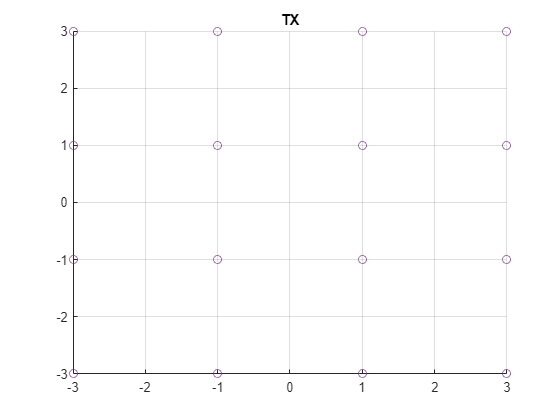

rng default
pilot_data = randsrc(length(pilot_index),ofdm_symbols,0:M-1);
P = qammod(pilot_data,M);
rng default
tx_data = randsrc(nfft,ofdm_symbols,0:M-1);
X = qammod(tx_data,M);
tx_data(pilot_index,:) = [];
X(pilot_index,:) = P;

figure(),scatter(real(X),imag(X)),title('TX'),grid on


x_pre_cp = ifft(X,nfft);
cp = x_pre_cp(nfft-cp_len+1:end,:);
x = vertcat(cp,x_pre_cp);

**Channel:**

x_channel = awgn(x,snr,'measured');
%%%%%%%%%%%%% Demod with only SNR
x_rx_snr = x_channel(cp_len+1:end,:);
X_RX_snr = fft(x_rx_snr,nfft);
%X_RX_snr = X_RX_snr(pilot_index,:);
x_channel = exp(-1i*pi/4)*x_channel;

x_channel = filter(multipath,1,x_channel);

**Demodulate:**

x_rx = x_channel(cp_len+1:end,:);
for i = 1:ofdm_symbols
    x_rx(:,i) = x_rx(:,i)*exp(-1j*0.6*i);
end
X_RX = fft(x_rx,nfft);
P_RX = X_RX(pilot_index,:);
%X_RX(pilot_index,:) = [];
H = conj(P_RX) ./ conj(P);
H_ZF = conj(H) ./ abs(H .* H);

Z_EQ = X_RX; Z_EQ2 = X_RX; Z_EQ3 = X_RX; Z_EQ4 = X_RX; Z_EQ5 = X_RX;
H_ZF2 = H_ZF; H_ZF3 = H_ZF;
% Normal ZF
for i=1:ofdm_symbols
    for k=1:length(pilot_index)
        index = ((rep)*(k-1)+1:(rep)*k);
        Z_EQ(index,i) = X_RX(index,i) * conj(H_ZF(k,i));
    end
end
% ZF with 1 interpolation point
for i=1:ofdm_symbols
    for k=1:length(pilot_index)
        index = ((rep)*(k-1)+1:(rep)*k);
        if (k ~= length(pilot_index))
            H_ZF2(k,i) = (H_ZF(k,i) + H_ZF(k+1,i))/2;
        end
        Z_EQ2(index,i) = X_RX(index,i) * conj(H_ZF2(k,i));
    end
end
% ZF with 3 interpolation points
% for i=1:ofdm_symbols
%     for k=1:length(pilot_index)
%         index = ((rep-1)*(k-1)+1:(rep-1)*k);
%         if (k ~= 8)
%             h_tmp2 = (H_ZF(k,i)+H_ZF(k+1,i))/2;
%             h_tmp3 = (h_tmp2+H_ZF(k+1,i))/2;
%             h_tmp1 = (H_ZF(k,i)+h_tmp2)/2;
%             H_tmp = [h_tmp1; h_tmp2; h_tmp3];
%         end
%         Z_EQ3(index,i) = X_RX(index,i) .* conj(H_tmp);
%     end
% end
% ZF phase only averaged accross 1 symbol
H_P = mean(H);
for i=1:ofdm_symbols
    Z_EQ3(:,i) = X_RX(:,i) * exp(1j*angle(H_P(i)));
end
P_RX2 = Z_EQ3(pilot_index,:);
H2 = conj(P_RX2) ./ conj(P);
H_ZF2 = conj(H2) ./ abs(H2 .* H2);
num_taps = 4;
% Stage 1 4-tap ZF equalizer
for i = 1:ofdm_symbols
    for k = 1:length(pilot_index)
        index = ((rep)*(k-1)+1:(rep)*k);
        if (k~=length(pilot_index)) && (i~=ofdm_symbols-2) && (i~=ofdm_symbols-1) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF2(k,i) H_ZF2(k+1,i) H_ZF2(k,i+1) H_ZF2(k+1,i+1) H_ZF2(k,i+2) H_ZF2(k+1,i+2) H_ZF2(k,i+3) H_ZF2(k+1,i+3)]);
        elseif (k~=length(pilot_index)) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF2(k,i) H_ZF2(k+1,i) H_ZF2(k,i+1) H_ZF2(k+1,i+1)]);
        elseif (k~=length(pilot_index))
            H_tmp = mean([H_ZF2(k,i) H_ZF2(k+1,i)]);
        end
        Z_EQ4(index,i) = Z_EQ3(index,i) .* conj(H_tmp);
    end
end
% Stage 1 4-tap ZF equalizer
for i = 1:ofdm_symbols
    for k = 1:length(pilot_index)
        index = ((rep)*(k-1)+1:(rep)*k);
        if (k~=length(pilot_index)) && (i~=ofdm_symbols-2) && (i~=ofdm_symbols-1) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF(k,i) H_ZF(k+1,i) H_ZF(k,i+1) H_ZF(k+1,i+1) H_ZF(k,i+2) H_ZF(k+1,i+2) H_ZF(k,i+3) H_ZF(k+1,i+3)]);
        elseif (k~=length(pilot_index)) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF(k,i) H_ZF(k+1,i) H_ZF(k,i+1) H_ZF(k+1,i+1)]);
        elseif (k~=length(pilot_index))
            H_tmp = mean([H_ZF(k,i) H_ZF(k+1,i)]);
        end
        Z_EQ5(index,i) = X_RX(index,i) .* conj(H_tmp);
    end
end

X_RX(pilot_index,:) = [];
Z_EQ(pilot_index,:) = [];
Z_EQ2(pilot_index,:) = [];
Z_EQ3(pilot_index,:) = [];
Z_EQ4(pilot_index,:) = [];
Z_EQ5(pilot_index,:) = [];

no_eq = qamdemod(X_RX,M);
zf_eq = qamdemod(Z_EQ,M);
zf_eq_1_interp = qamdemod(Z_EQ2,M);
zf_eq_1_interp_4_tap = qamdemod(Z_EQ5,M);
zf_eq_2_stage = qamdemod(Z_EQ4,M);

no_eq_ser = symerr(tx_data,no_eq)/numel(tx_data);
zf_eq_ser = symerr(tx_data,zf_eq)/numel(tx_data);
zf_eq_1_interp_ser = symerr(tx_data,zf_eq_1_interp)/numel(tx_data);
zf_eq_1_interp_4_tap_ser = symerr(tx_data,zf_eq_1_interp_4_tap)/numel(tx_data);
zf_eq_2_stage_ser = symerr(tx_data,zf_eq_2_stage)/numel(tx_data);

X(pilot_index,:) = [];
evm = comm.EVM(AveragingDimensions=[1 2],MaximumEVMOutputPort=1);
[no_eq_evm,no_eq_pk] = evm(X,X_RX);
[zf_eq_evm,zf_eq_pk] = evm(X,Z_EQ) ;
[zf_eq_1_interp_evm,zf_eq_1_interp_pk] = evm(X,Z_EQ2);
[zf_eq_1_interp_4_tap_evm,zf_eq_1_interp_4_tap_pk] = evm(X,Z_EQ3);
[zf_eq_2_stage_evm,zf_eq_2_stage_pk] = evm(X,Z_EQ4);

Equalization = ["No Equalization";"ZF";"Interpolated ZF";"4-Tap Interpolated ZF";"2-Stage ZF"];
SER = [no_eq_ser;zf_eq_ser;zf_eq_1_interp_ser;zf_eq_1_interp_4_tap_ser;zf_eq_2_stage_ser];
AverageEVM = [no_eq_evm;zf_eq_evm;zf_eq_1_interp_evm;zf_eq_1_interp_4_tap_evm;zf_eq_2_stage_evm];
PeakEvm = [no_eq_pk;zf_eq_pk;zf_eq_1_interp_pk;zf_eq_1_interp_4_tap_pk;zf_eq_2_stage_pk];

table(Equalization,SER,AverageEVM,PeakEvm)

ans = 5×4 table
         Equalization             SER        AverageEVM    PeakEvm
    _______________________    __________    __________    _______

    "No Equalization"               0.865      142.58      307.93 
    "ZF"                        0.0042188      12.392      90.099 
    "Interpolated ZF"          0.00020833      10.131      60.621 
    "4-Tap Interpolated ZF"       0.94672      21.276      47.398 
    "2-Stage ZF"                        0      8.0392      31.319 


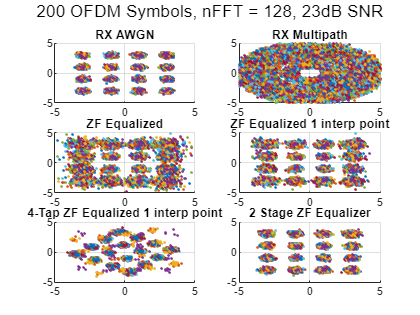


%y_lim = [-2 2]; x_lim = [-2 2];
y_lim = [-5 5]; x_lim = [-5 5]; % 16 QAM
%y_lim = [-9 9]; x_lim = [-9 9]; % 64 QAM
%y_lim = [-15 15]; x_lim = [-15 15]; % 128 QAM
%y_lim = [-19 19]; x_lim = [-19 19]; % 256 QAM
figure(),subplot(3,2,1),scatter(real(X_RX_snr),imag(X_RX_snr),'.','LineWidth',2),grid on,title('RX AWGN'),xlim(x_lim),ylim(y_lim)
subplot(3,2,2),scatter(real(X_RX),imag(X_RX),'.','lineWidth',2),grid on,title('RX Multipath'),xlim(x_lim),ylim(y_lim)
subplot(3,2,3),scatter(real(Z_EQ),imag(Z_EQ),'.','lineWidth',2),grid on,title('ZF Equalized'),xlim(x_lim),ylim(y_lim)
subplot(3,2,4),scatter(real(Z_EQ2),imag(Z_EQ2),'.','lineWidth',2),grid on,title('ZF Equalized 1 interp point'),xlim(x_lim),ylim(y_lim)
subplot(3,2,5),scatter(real(Z_EQ5),imag(Z_EQ5),'.','lineWidth',2),grid on,title('4-Tap ZF Equalized 1 interp point'),xlim(x_lim),ylim(y_lim)
subplot(3,2,6),scatter(real(Z_EQ4),imag(Z_EQ4),'.','LineWidth',2),grid on,title('2 Stage ZF Equalizer'),xlim(x_lim),ylim(y_lim)
sgtitle([num2str(ofdm_symbols),' OFDM Symbols, nFFT = ',num2str(nfft),', ',num2str(snr),'dB SNR'])

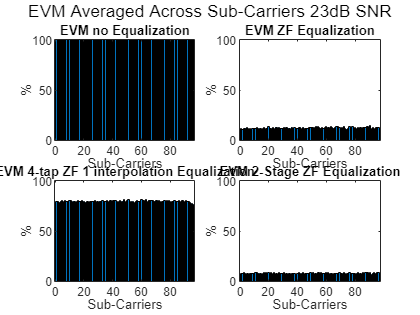

% Plot EVM vs Subcarriers 
evm = comm.EVM(AveragingDimensions=2);
no_eq_evm = evm(X,X_RX);
zf_eq_evm = evm(X,Z_EQ) ;
zf_eq_1_interp_evm = evm(X,Z_EQ2);
zf_eq_1_interp_4_tap_evm = evm(X,Z_EQ5);
zf_eq_2_stage_evm = evm(X,Z_EQ4);

y_lim = [0 100];
figure(),subplot(2,2,1),bar(1:nfft-cp_len,no_eq_evm),title('EVM no Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,2),bar(1:nfft-cp_len,zf_eq_evm),title('EVM ZF Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,3),bar(1:nfft-cp_len,zf_eq_1_interp_4_tap_evm),title('EVM 4-tap ZF 1 interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,4),bar(1:nfft-cp_len,zf_eq_2_stage_evm),title('EVM 2-Stage ZF Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
sgtitle(['EVM Averaged Across Sub-Carriers ',num2str(snr),'dB SNR'])

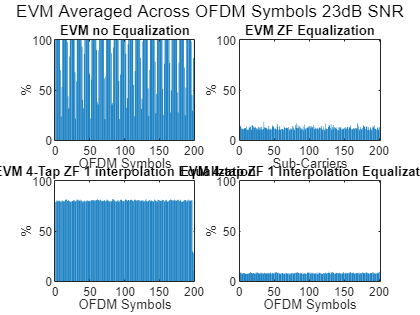

% Plot EVM vs OFDM Symbols
evm = comm.EVM(AveragingDimensions=1);
no_eq_evm = evm(X,X_RX);
zf_eq_evm = evm(X,Z_EQ) ;
zf_eq_1_interp_evm = evm(X,Z_EQ2);
zf_eq_1_interp_4_tap_evm = evm(X,Z_EQ5);
zf_eq_2_stage_evm = evm(X,Z_EQ4);

y_lim = [0 100];
figure(),subplot(2,2,1),bar(1:ofdm_symbols,no_eq_evm),title('EVM no Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
subplot(2,2,2),bar(1:ofdm_symbols,zf_eq_evm),title('EVM ZF Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,3),bar(1:ofdm_symbols,zf_eq_1_interp_4_tap_evm),title('EVM 4-Tap ZF 1 interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
subplot(2,2,4),bar(1:ofdm_symbols,zf_eq_2_stage_evm),title('EVM 4-tap ZF 1 Interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
sgtitle(['EVM Averaged Across OFDM Symbols ',num2str(snr),'dB SNR'])

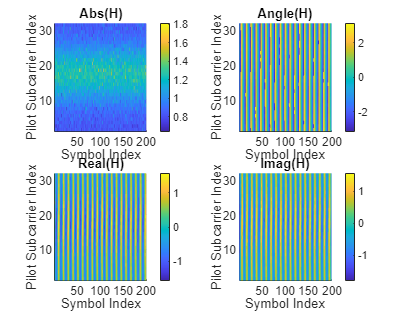

figure(),subplot(2,2,1),s = surf(abs(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Abs(H)')
subplot(2,2,2),s = surf(angle(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Angle(H)')
subplot(2,2,3),s = surf(real(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Real(H)')
subplot(2,2,4),s = surf(imag(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Imag(H)')